clear
close all

## Trabalho Computacional I - Questão 1

**Alunos:**

- Daniel da Rocha Carneiro

- Leon Lima Santos

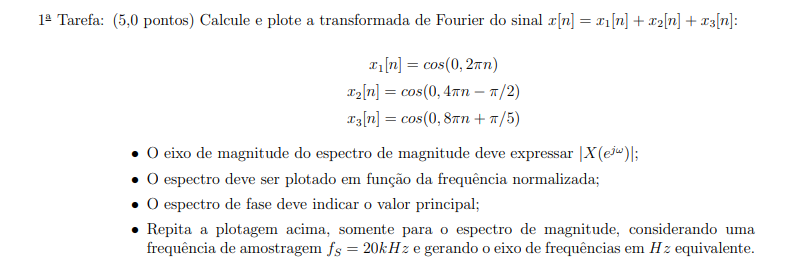

### **Resposta para uma taxa de amostragem Fs**

Inicou-se definindo os parâmetros para análise discreta e definindo os vetores de tempo e frequência normalizada:

Fs = 100;       % Frequência de amostragem em Hz
Fn = Fs/2;                              % Frequência de Nyquist
T = 1/Fs;                               % Período de amostragem       
L = 10*Fs;                              % Duração do sinal
n = (0:L-1)*T;                          % Vetor de tempo
N = numel(n);                           % Tamanho do vetor
Freq = linspace(-Fn, Fn, numel(n));     % Eixo de frequência normalizada

Então, declarou-se os valores das funções que compõem o sinal x[n]:

x1 = cos(0.2*pi*n);                     % x1[n]
x2 = cos(0.4*pi*n-(pi/2));              % x2[n]
x3 = cos(0.8*pi*n+(pi/5));              % x3[n]

x  = x1 + x2 + x3;                      % x[n]

O sinal x[n] pode ser esboçado da forma a seguir:

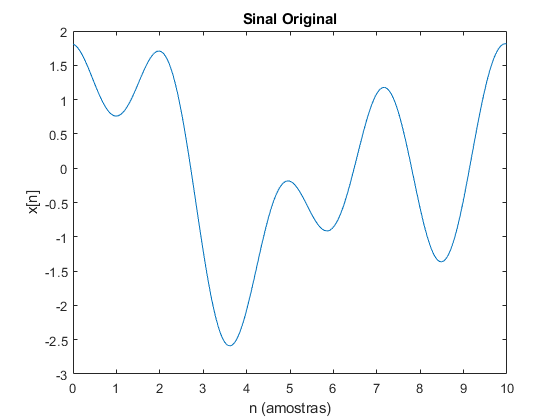

plot(n,x)                                
title("Sinal Original")
xlabel("n (amostras)")
ylabel("x[n]")

Calcula-se a transformada de Fourrier do sinal, utilizando o algoritmo Fast Fourrier Transform:

X = fft(x);

Com a transformada, é possível calcular o espectro de magnitude em função da frequência normalizada:

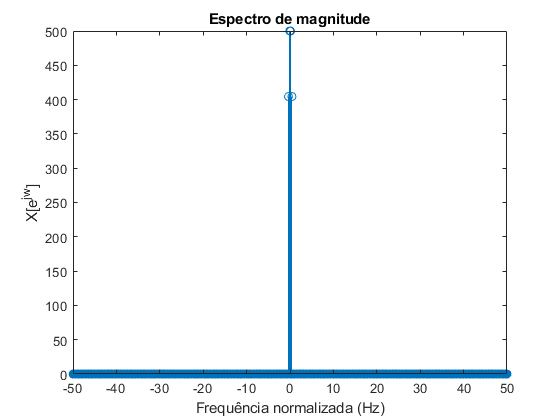

stem(Freq,fftshift(abs(real(X))));      % Utilizado fftshift para centralizar o espectro em torno da frequência 0;
%plot(Freq,fftshift(abs(real(X))));     % Função caso x[n] fosse contínuo 
title("Espectro de magnitude")
xlabel("Frequência normalizada (Hz)")
ylabel("X[e^{jw}]")

Também é possível esboçar o espectro de fase:

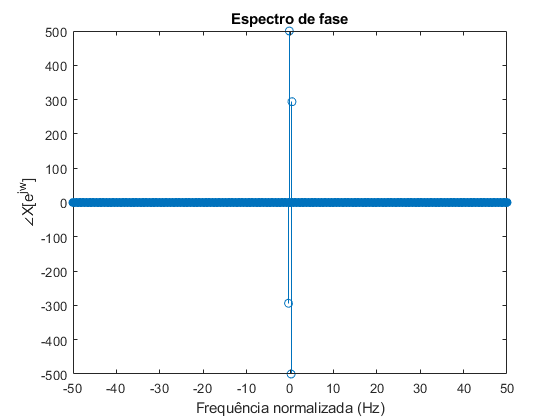

figure
stem(Freq,fftshift(imag(X))); % Utilizado fftshift para centralizar o espectro em torno da frequência 0;        
title("Espectro de fase")
xlabel("Frequência normalizada (Hz)")
ylabel("∠X[e^{jw}]")

Para facilitar a leitura, implementou-se a função *identificarPicos* para informar os valores diferentes de aproximadamente 0:

identificarPicos(fftshift(real(X)),0.1)

ans =   500.0000  500.0000  404.5085  404.5085


### **Espectro para 20kHz**

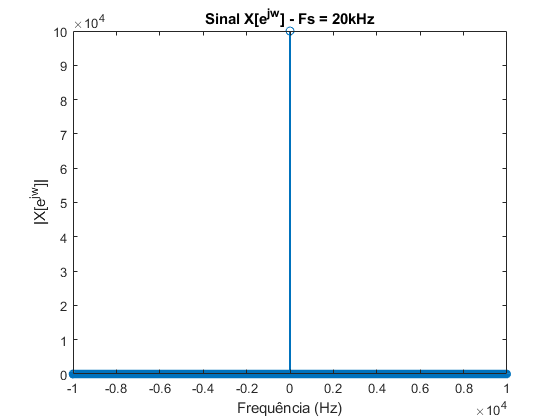

figure
plotMagnitude(20000)

### **Comparação entre diferentes taxas de amostragem**

Define-se as taxas de amostragem desejadas:

Fs1 = 1;       % Frequência de amostragem em Hz
Fs2 = 5;       % Frequência de amostragem em Hz
Fs3 = 100;       % Frequência de amostragem em Hz
Fs4 = 20000;       % Frequência de amostragem em Hz


E então é possível gerar a comparação do sinal:

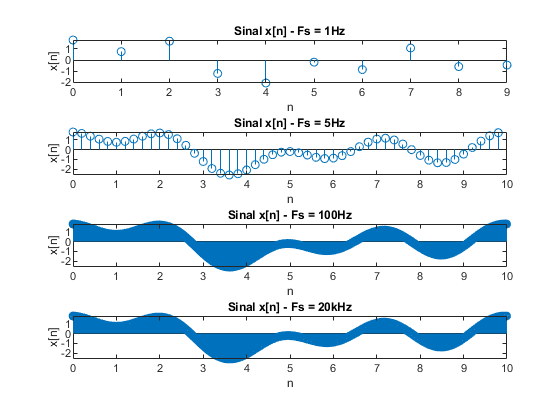


figure
hold on
subplot(4,1,1)
plotSinal(Fs1)
subplot(4,1,2)
plotSinal(Fs2)
subplot(4,1,3)
plotSinal(Fs3)
subplot(4,1,4)
plotSinal(Fs4)

E da sua resposta em magnitude:

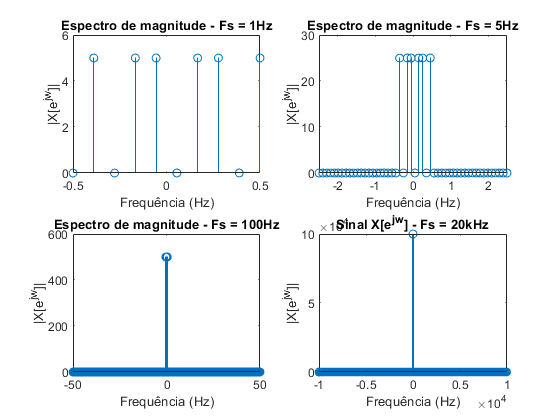

figure
hold on
subplot(2,2,1)
plotMagnitude(Fs1)
subplot(2,2,2)
plotMagnitude(Fs2)
subplot(2,2,3)
plotMagnitude(Fs3)
subplot(2,2,4)
plotMagnitude(Fs4)

### Análise do aliasing

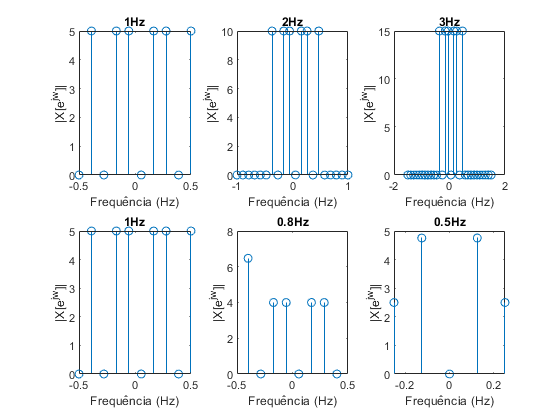

figure
hold on
subplot(2,3,1)
plotMagnitude(1, "1Hz")
subplot(2,3,2)
plotMagnitude(2, "2Hz")
subplot(2,3,3)
plotMagnitude(3, "3Hz")
subplot(2,3,4)
plotMagnitude(1, "1Hz")
subplot(2,3,5)
plotMagnitude(0.8, "0.8Hz")
subplot(2,3,6)
plotMagnitude(0.5, "0.5Hz")

function [picos] = identificarPicos(entrada, limite) %Função para facilitar a identificação dos impulsos encontrados
    entrada(abs(entrada)<limite) = 0;
    picos = findpeaks(entrada);
    picos = sort(picos, 'descend');
end

%% Funções para facilitar a plotagem de sinais com taxas de amostragem diferentes
function plotSinal(Fs, name)
    [x, n, ~, ~] = calculaTransformada(Fs);
    stem(n,x);
    if ~exist("name", "var")
        title(sprintf("Sinal x[n] - Fs = %dHz", Fs))
        if Fs>=1000
            title(sprintf("Sinal x[n] - Fs = %dkHz", Fs/1000))
        end
    else
        title(name)
    end
    xlabel("n")
    ylabel("x[n]")
end

function plotMagnitude(Fs, name)
    [~, ~, X, Freq] = calculaTransformada(Fs);
    stem(Freq,fftshift(abs(X)));
    if ~exist("name", "var")
        title(sprintf("Espectro de magnitude - Fs = %dHz", Fs))
        if Fs>=1000
            title(sprintf("Sinal X[e^{jw}] - Fs = %dkHz", Fs/1000))
        end    
    else
        title(name)
    end

    xlabel("Frequência (Hz)")
    ylabel("|X[e^{jw}]|")            
end

function [x, n, X, Freq] = calculaTransformada(Fs)
Fn = Fs/2;                              % Frequência de Nyquist
T = 1/Fs;                               % Período de amostragem       
L = 10*Fs;                              % Duração do sinal
n = (0:L-1)*T;                          % Vetor de tempo
N = numel(n);                           % Tamanho do vetor
Freq = linspace(-Fn, Fn, numel(n));     % Eixo de frequência normalizada
x1 = cos(0.2*pi*n);                     % x1[n]
x2 = cos(0.4*pi*n-(pi/2));              % x2[n]
x3 = cos(0.8*pi*n+(pi/5));              % x3[n]
x  = x1 + x2 + x3;                      % x[n]
X = fft(x);                             % Transformada do sinal
end

